clc; clear; 
A = [2 -1 1; -3 -1 2; -2 1 2];
b = [8; -11; -3];

solution = gaussElimination(A, b);


fprintf('The solution is:\n');

The solution is:


disp(solution);

    4.1333
    1.9333
    1.6667




function x = gaussElimination(A,b)
    n = length(b);
    Aug = [A b];
    for k = 1:n-1
        for i = k+1:n
            factor = Aug(i,k)/Aug(k,k);
            Aug(i,k:n+1) = Aug(i,k:n+1)- factor*Aug(k,k:n+1);
        end
    end
    x = zeros(n,1);
    x(n) = Aug(n,n+1)/Aug(n,n);
    for i = n-1:-1:1
        sum_val = Aug(i,n+1); 
        for j=i+1:n
            sum_val = sum_val - Aug(i,j)*x(j);
        end
        x(i) = sum_val / Aug(i,i);
    end
end


clc; clear; 
A = [1e-5 1 1; 1 1 1; 1 2 3];
b = [2; 3; 6];


solution = GEPartialPivoting(A, b);


fprintf('The solution is:\n');

The solution is:


disp(solution);

    1.0000
    1.0000
    1.0000




function x = GEPartialPivoting(A,b)
    n = length(b);
    Aug = [A b];
    for k = 1:n-1
        [~, m] = max(abs(Aug(k:n, k)));
        m = m + k - 1; 
        Aug([k m], :) = Aug([m k], :);
        for i = k+1:n
            factor = Aug(i,k) / Aug(k,k);
            Aug(i, k:n+1) = Aug(i, k:n+1) - factor * Aug(k, k:n+1);
        end
    end
    x = zeros(n, 1); 
    x(n) = Aug(n, n+1) / Aug(n, n);
    for i = n-1:-1:1
        x(i) = (Aug(i, n+1) - Aug(i, i+1:n) * x(i+1:n)) / Aug(i, i);
    end
end

clc; clear;

A = [10 -1 2 0; -1 11 -1 3; 2 -1 10 -1; 0 3 -1 8];
b = [6; 25; -11; 15];
tol = 1e-4;
max_iter = 100;

solution = jacobi_method(A, b, tol, max_iter);

Converged in 13 iterations.
    Iteration      x1         x2         x3         x4         Error   
    _________    _______    ______    ________    _______    __________

        1            0.6    2.2727        -1.1      1.875        2.2727
        2         1.0473    1.7159    -0.80523    0.88523       0.98977
        3        0.93264    2.0533     -1.0493     1.1309        0.3374
        4         1.0152    1.9537    -0.96811    0.97384       0.15704
        5        0.98899    2.0114     -1.0103     1.0214      0.057719
        6         1.0032    1.9922    -0.99452    0.99443      0.026917
        7        0.99813    2.0023      -1.002     1.0036      0.010066
        8         1.0006    1.9987    -0.99904    0.99889     0.0047059
        9        0.99967    2.0004     -1.0004 

disp('Final Solution:');

Final Solution:


disp(solution);

    1.0000
    2.0000
   -1.0000
    1.0000




function x = jacobi_method(A, b, tol, max_iter)
    n = length(b);
    x = zeros(n, 1);
    x_old = x;
    history = [];
    
    for k = 1:max_iter
        for i = 1:n
            sum_val = 0;
            for j = 1:n
                if j ~= i
                    sum_val = sum_val + A(i,j) * x_old(j);
                end
            end
            x(i) = (b(i) - sum_val) / A(i,i);
        end
        
        current_error = norm(x - x_old, inf);
        history = [history; k, x', current_error];
        
        if current_error < tol
            fprintf('Converged in %d iterations.\n', k);
            T = array2table(history, 'VariableNames', {'Iteration', 'x1', 'x2', 'x3', 'x4', 'Error'});
            disp(T);
            return;
        end
        
        x_old = x; 
    end
end

clc; clear;
X = [2; 1]; 
tol = 1e-6;
max_iter = 100;

for k = 1:max_iter
    F = [X(1)^2 + X(2)^2 - 9; 
         X(1) - X(2) - 1];
    
    J = [2*X(1), 2*X(2); 
         1, -1];
    
    delta = J \ (-F);
    X = X + delta;
    
    if norm(delta) < tol
        fprintf('converged in %d iterations.\n', k);
        break;
    end
end

converged in 5 iterations.


disp('Solution (x, y):');

Solution (x, y):


disp(X);

    2.5616
    1.5616



A = [10, -2, -1; 
    -2, 10, -1; 
    -1, -1, 10];
b = [3; 15; 27];
n = length(b);
tol = 1e-6;
max_iter = 100;

Xj = zeros(n, 1);
err_j = [];
for k = 1:max_iter
    X_old = Xj;
    for i = 1:n
        S = A(i, :) * X_old - A(i, i) * X_old(i);
        Xj(i) = (b(i) - S) / A(i, i);
    end
    diff = norm(Xj - X_old, inf);
    err_j = [err_j, diff];
    if diff < tol
        break;
    end
end

Xg = zeros(n, 1);
err_g = [];
for k = 1:max_iter
    X_old = Xg;
    for i = 1:n
        S1 = A(i, 1:i-1) * Xg(1:i-1);
        S2 = A(i, i+1:n) * X_old(i+1:n);
        Xg(i) = (b(i) - S1 - S2) / A(i, i);
    end
    diff = norm(Xg - X_old, inf);
    err_g = [err_g, diff];
    if diff < tol
        break;
    end
end

disp('Jacobi Solution:');

Jacobi Solution:


disp(Xj);

    1.0000
    2.0000
    3.0000



disp('Gauss-Seidel Solution:');

Gauss-Seidel Solution:


disp(Xg);

    1.0000
    2.0000
    3.0000



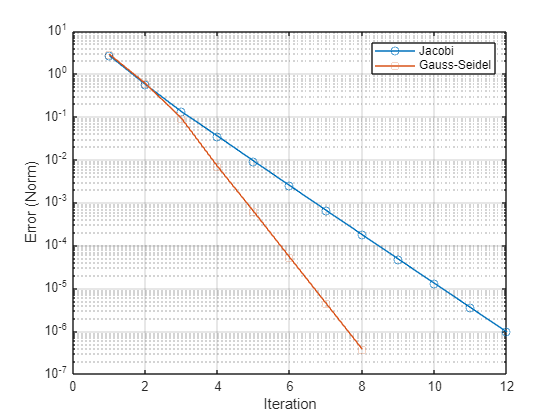


semilogy(1:length(err_j), err_j, '-o', 1:length(err_g), err_g, '-s');
xlabel('Iteration');
ylabel('Error (Norm)');
legend('Jacobi', 'Gauss-Seidel');
grid on;

clc;
clear;

X = [0.5; 1; 1.5]; 
tol = 1e-6;
max_iter = 20;

for k = 1:max_iter
    F = [X(1) + X(2) + X(3) - 3;
         X(1)^2 + X(2)^2 + X(3)^2 - 5;
         X(1) - X(2) + X(3) - 1];
    
    J = [1, 1, 1;
         2*X(1), 2*X(2), 2*X(3);
         1, -1, 1];
    
    dX = J \ (-F);
    X = X + dX;
    
    if norm(dX) < tol
        fprintf('Converged in %d iterations\n', k);
        break;
    end
end

Converged in 5 iterations


    
fprintf('Solution:\n');

Solution:


fprintf('x = %f\n', X(1));

x = -0.000000


fprintf('y = %f\n', X(2));

y = 1.000000


fprintf('z = %f\n', X(3));

z = 2.000000


clc; clear;

converged in 7 iterations.


Tension values (x, y):


    1.3608
    0.1482



X = [1; 1]; 
tol = 1e-6;
max_iter = 100;

for k = 1:max_iter
    F = [sin(X(1)) + X(2)^2 - 1;
         X(1)^2 + X(2) - 2];
    
    J = [cos(X(1)), 2*X(2);
         2*X(1), 1];
    
    dX = J \ (-F);
    X = X + dX;
    
    if norm(dX) < tol
        fprintf('converged in %d iterations.\n', k);
        break;
    end
end
disp('Tension values (x, y):');
disp(X);